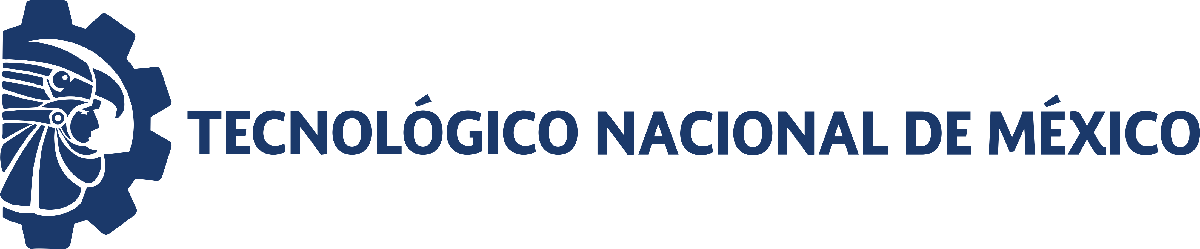                                 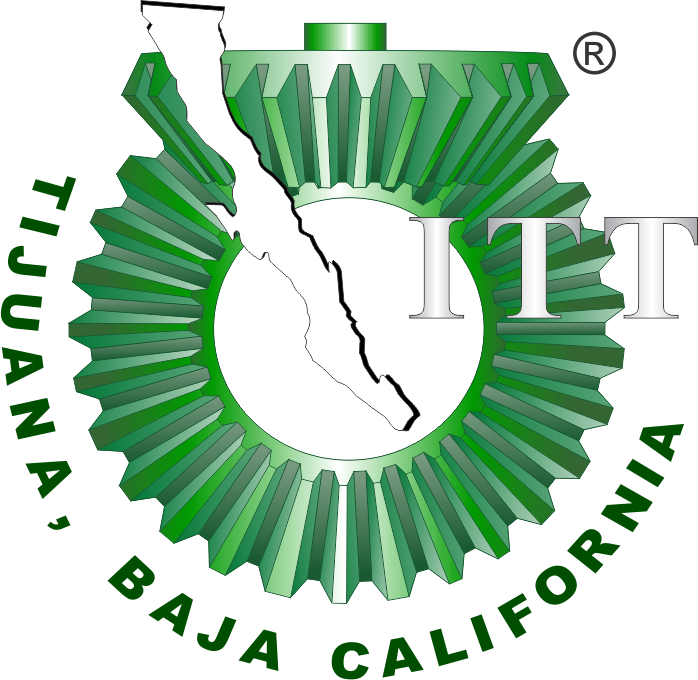

# Práctica cuatro: Modelado y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

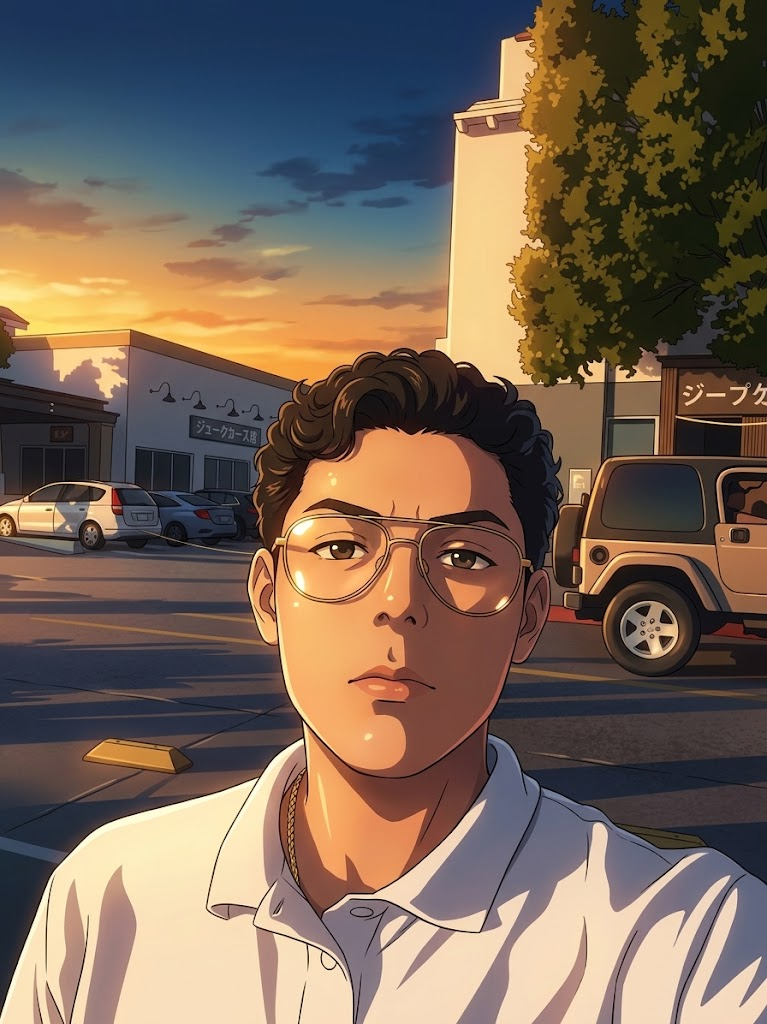

Nombre del alumno: **Christian** **Cid Pacheco**

Número de control: **23212186**

Correo institucional:** l23212186@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema.slx',parameters);
t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t, 'previous')

Pa =     0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420


writematrix(Pa,'signal.xlsx');

## Respuesta: Hipotenso, Normotenso, Hipertenso

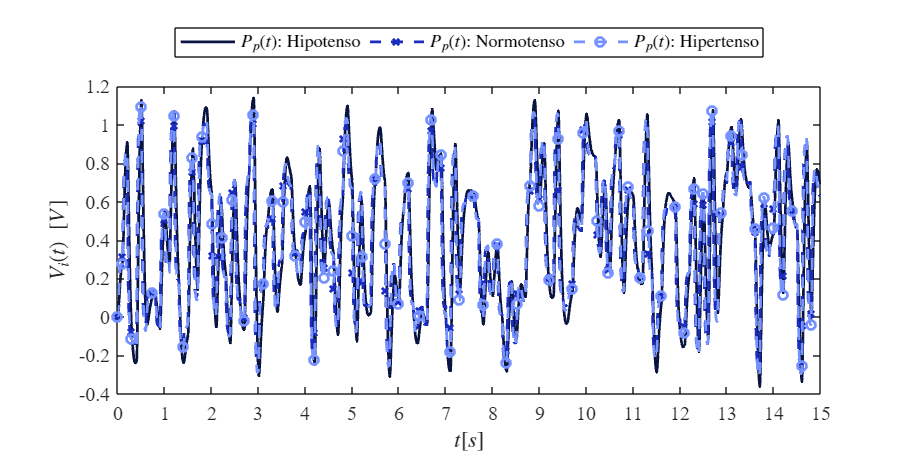

plotsignals(x.t, x.PpL, x.PpN, x.PpH, x.PIDL, x.PIDH, 'Senal');

## Respuesta: Hipotenso

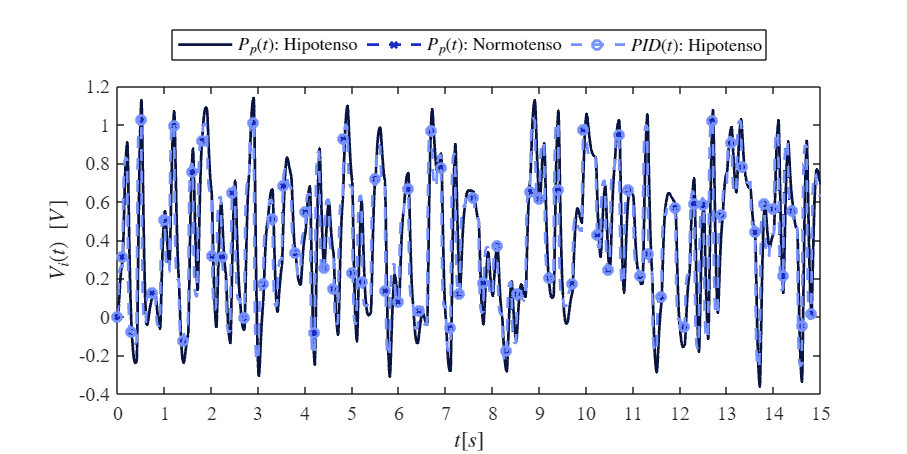

plotsignals(x.t, x.PpL, x.PpN, x.PpH, x.PIDL, x.PIDH, 'Hipotenso');

## Respuesta: Hipertenso

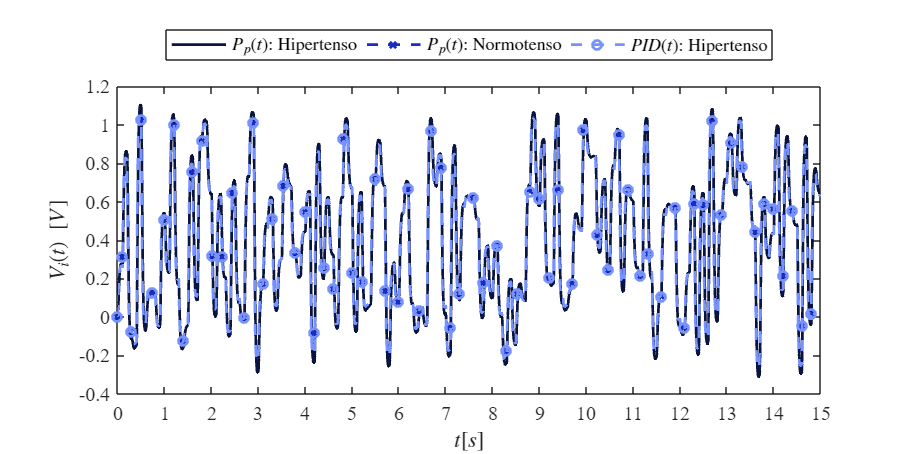

plotsignals(x.t, x.PpL, x.PpN, x.PpH, x.PIDL, x.PIDH, 'Hipertenso');

## Modelo de EDOs

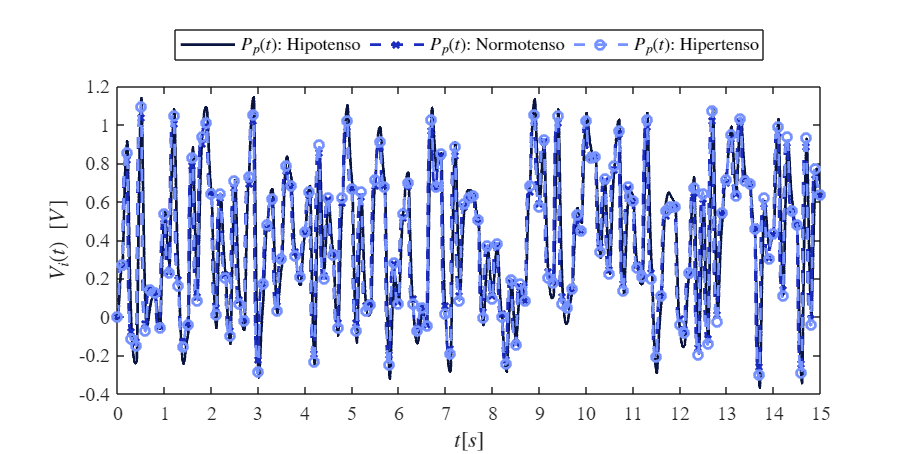

par_hipo = [0.010,0.001,1.000,3.500]; %[Z,L,R,C]
par_normo = [0.010,0.001,1.000,1.500];
par_hiper = [0.010,0.001,1.000,1.000];
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t, PpL, PpN, PpH, [], [], 'Senal');

function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4);
    dt = t(2);
    n = round(t(end)/dt);
    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L) * Pp(i) + (1/L) * Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C) * FL(i) - (1/(Z*C) + 1/(R*C)) * Pp(i) + 1/(Z*C) * Pa(i))*dt;
    end
end

## Funcion: Respuestas de la simulacion

function plotsignals (t, PpL, PpN, PpH, PIDL, PIDH, signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [9, 21, 64]/255;
    clr2 = [27, 44, 193]/255;
    clr3 = [118, 146, 255]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    if signal == "Senal"
        plot(t, PpL, '-', t, PpN, '--x', t, PpH, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1e2:length(t));
        L = legend('$P_{p}(t)$: Hipotenso', '$P_{p}(t)$: Normotenso', '$P_{p}(t)$: Hipertenso');
        
    elseif signal == "Hipotenso"
        plot(t, PpL, '-', t, PpN, '--x', t, PIDL, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1e2:length(t));
        L = legend('$P_{p}(t)$: Hipotenso', '$P_{p}(t)$: Normotenso', '$PID(t)$: Hipotenso');
        
    elseif signal == "Hipertenso"
        plot(t, PpH, '-', t, PpN, '--x', t, PIDH, '--o', ...
            'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1e2:length(t));
        L = legend('$P_{p}(t)$: Hipertenso', '$P_{p}(t)$: Normotenso', '$PID(t)$: Hipertenso');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t[s]$','interpreter','latex')
    ylabel('$V_i(t)\ [V]$','interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    if signal == "Senal"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
    elseif signal == "Hipotenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
    elseif signal == "Hipertenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
    end

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')
end